Full tb data - combined from tb from original INDIGO paper and tb from Suraj's paper and tb from new paper

%Test for combined tb data

testFile = 'tb_full.xlsx';
trainingData = 'orig_ecoli.xlsx';
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;

summaryTable = 1×12 table
      min      median     max      range       mean        std      interactionCount    synergyCount    antagonismCount    orthologsCount    rejectNormality    pNormality
    _______    ______    ______    ______    _________    ______    ________________    ____________    _______________    ______________    _______________    __________

    -2.1844      0       2.0875    4.2719    -0.096767    0.6811           95                36               37                3190              true            0.0005  


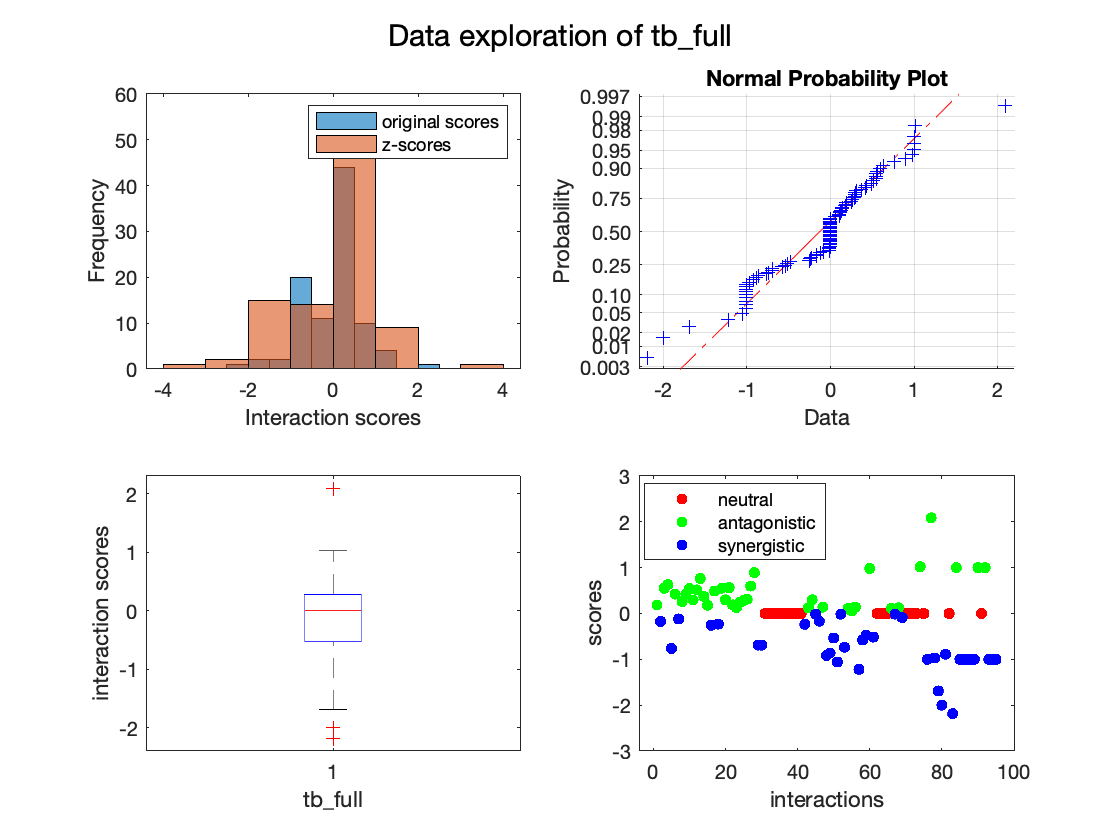

[summary,drugList] = dataExplore(testFile);

indigoSummary = indigoRun(testFile,trainingData,valMethod,K, standardize,input_type);

Run 1
Elapsed time is 4.699989 seconds.
Run 2
Elapsed time is 4.945977 seconds.
Run 3
Elapsed time is 5.199416 seconds.
Run 4
Elapsed time is 4.753950 seconds.
Run 5
Elapsed time is 4.577245 seconds.


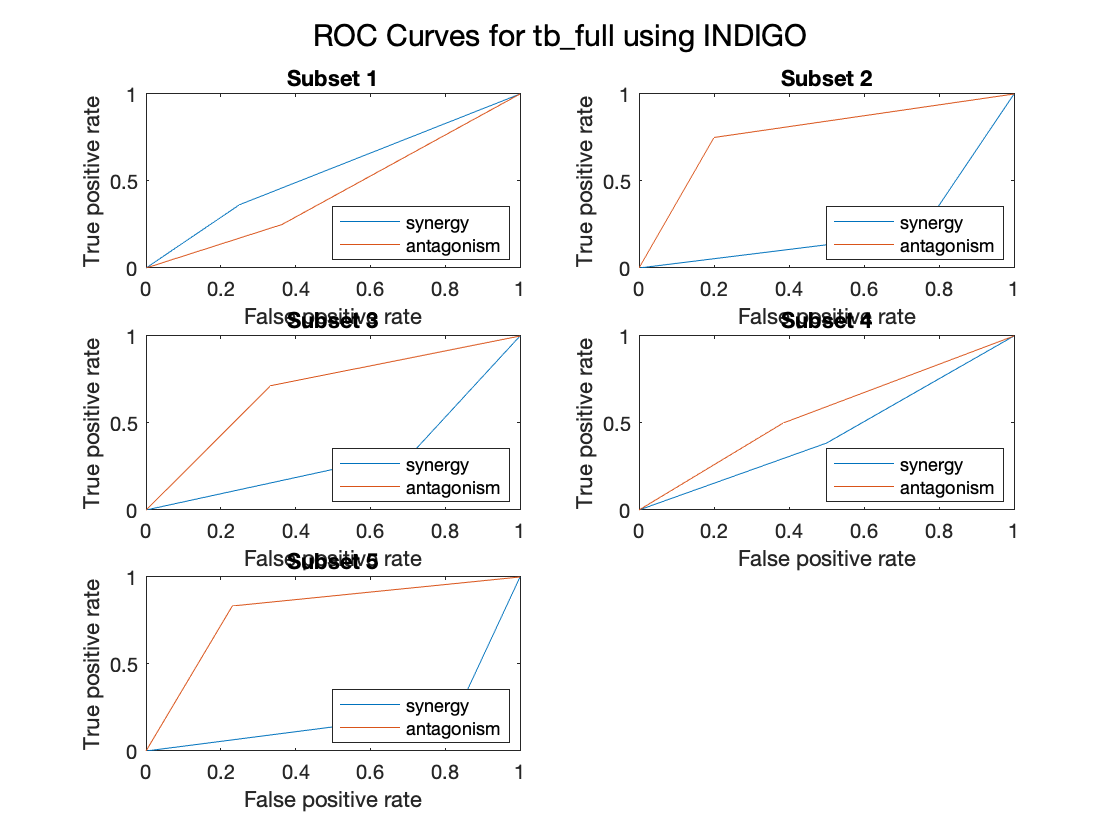

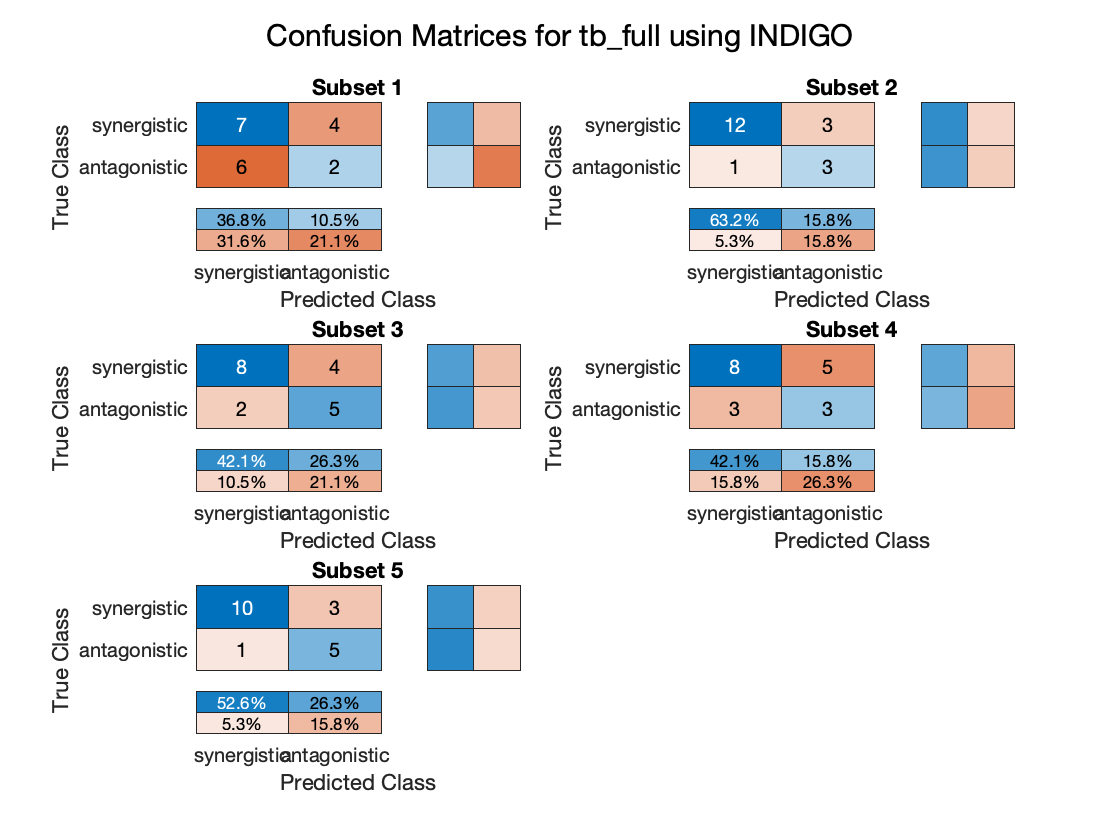

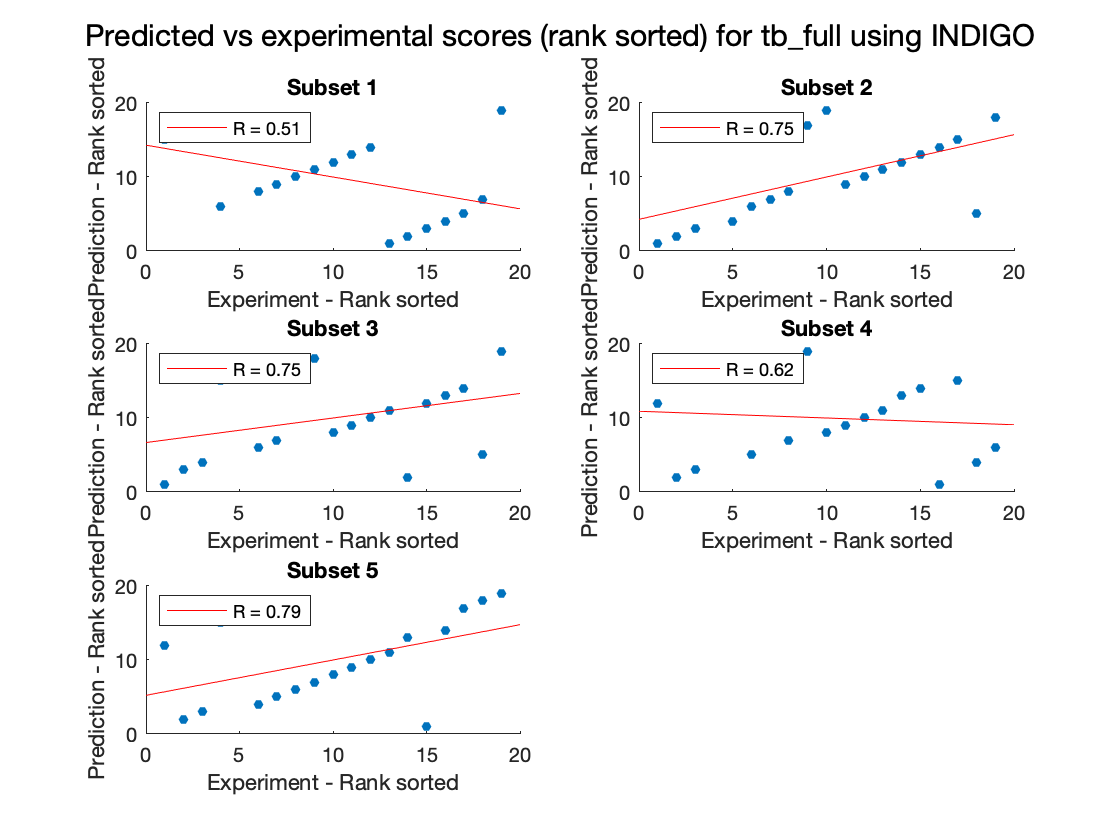

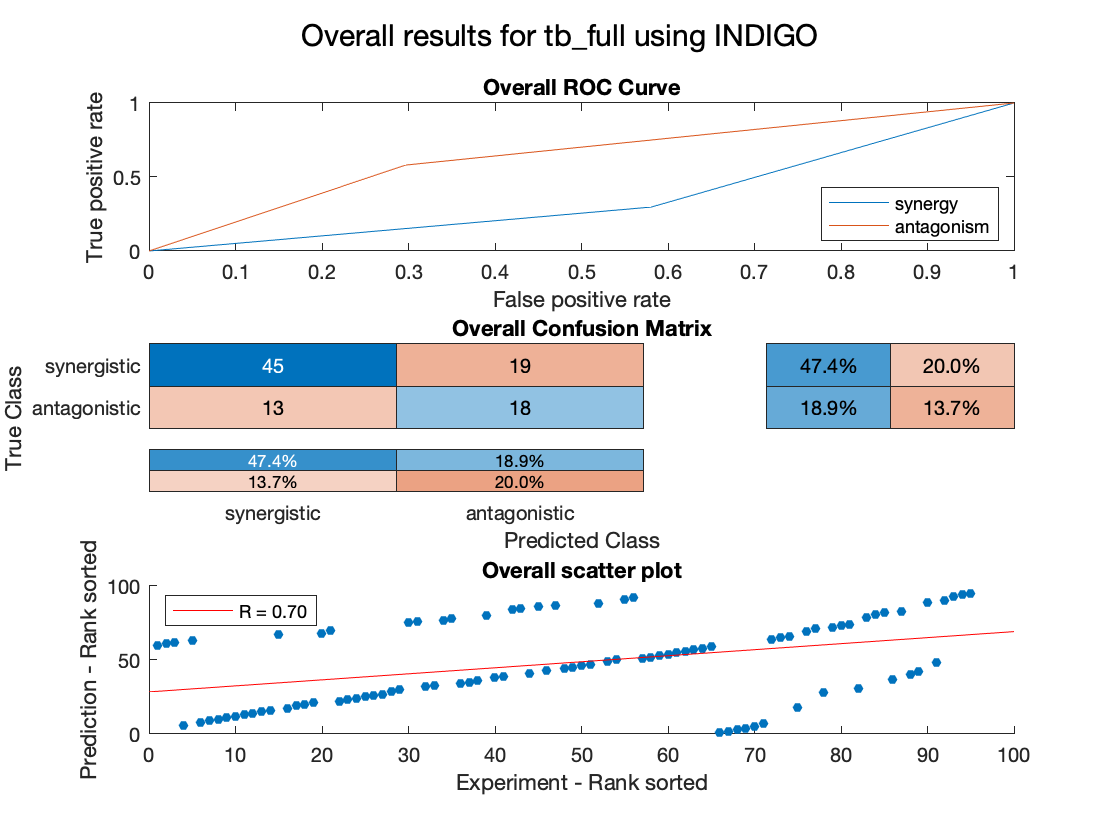

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         19         0.50532 

averagesTable = 12×1 table
                                  Value   
                                __________

    Interactions                        19
    R (rank)                       0.68203
    P value                      0.0064851
    Accuracy                       0.66316
    Absolute error                 0.67368
    Precision (synergy)            0.77958
    Recall (synergy)               0.69753
    Precision (antagonism)         0.47778
    Recall (antagonism)            0.60952
    Guess Accuracy (p value)    1.1213e-10
    AUC - ROC (synergy)            0.34647
    AUC - ROC (antagonism)         0.65353


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        95
    R (rank)                       0.70327
    P value                     1.9254e-15
    Accuracy                       0.66316
    Absolute error                 0.67368
    Precision (synergy)            0.77586
    Recall (synergy)               0.70312
    Precision (antagonism)         0.48649
    Recall (antagonism)            0.58065
    Guess Accuracy (p value)    1.5938e-61
    AUC - ROC (synergy)            0.35811
    AUC - ROC (antagonism)         0.64189


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_full.xlsx';
trainingData = 'orig_ecoli.xlsx';
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K, standardize,input_type);

Run 1
Elapsed time is 4.864888 seconds.
Run 2
Elapsed time is 5.227287 seconds.
Run 3
Elapsed time is 5.286508 seconds.
Run 4
Elapsed time is 5.145835 seconds.
Run 5
Elapsed time is 5.177886 seconds.


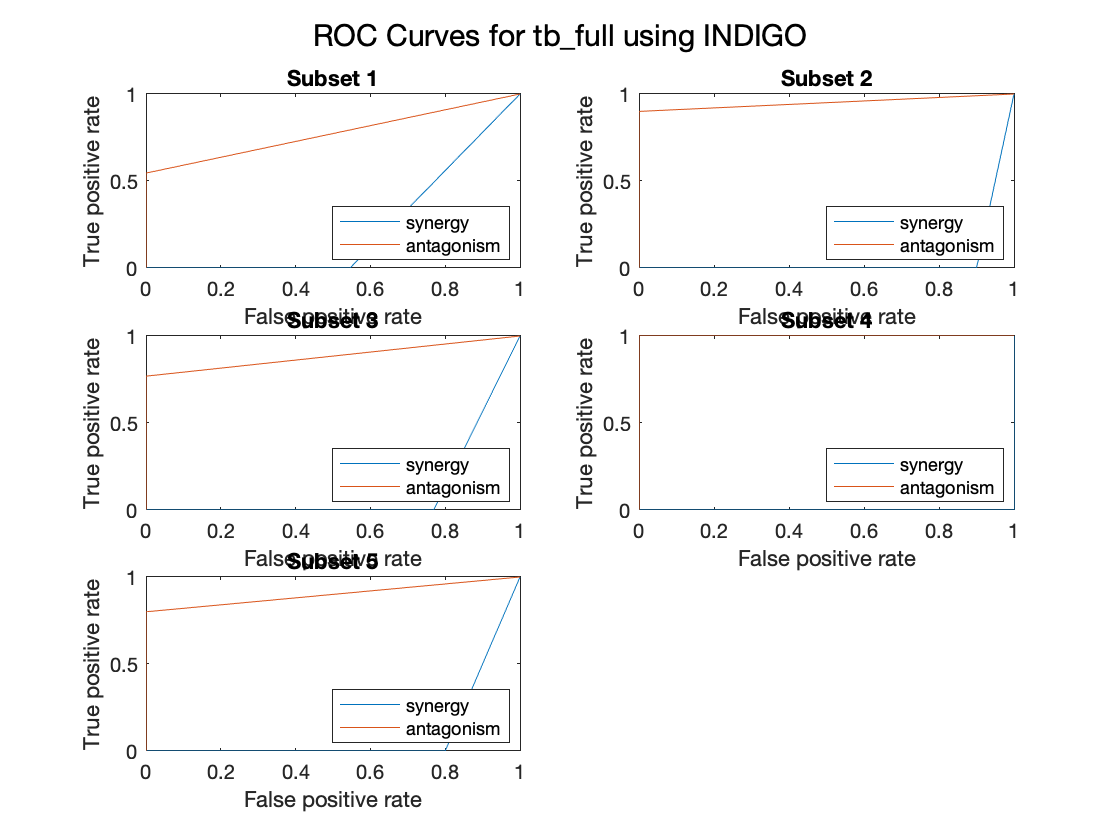

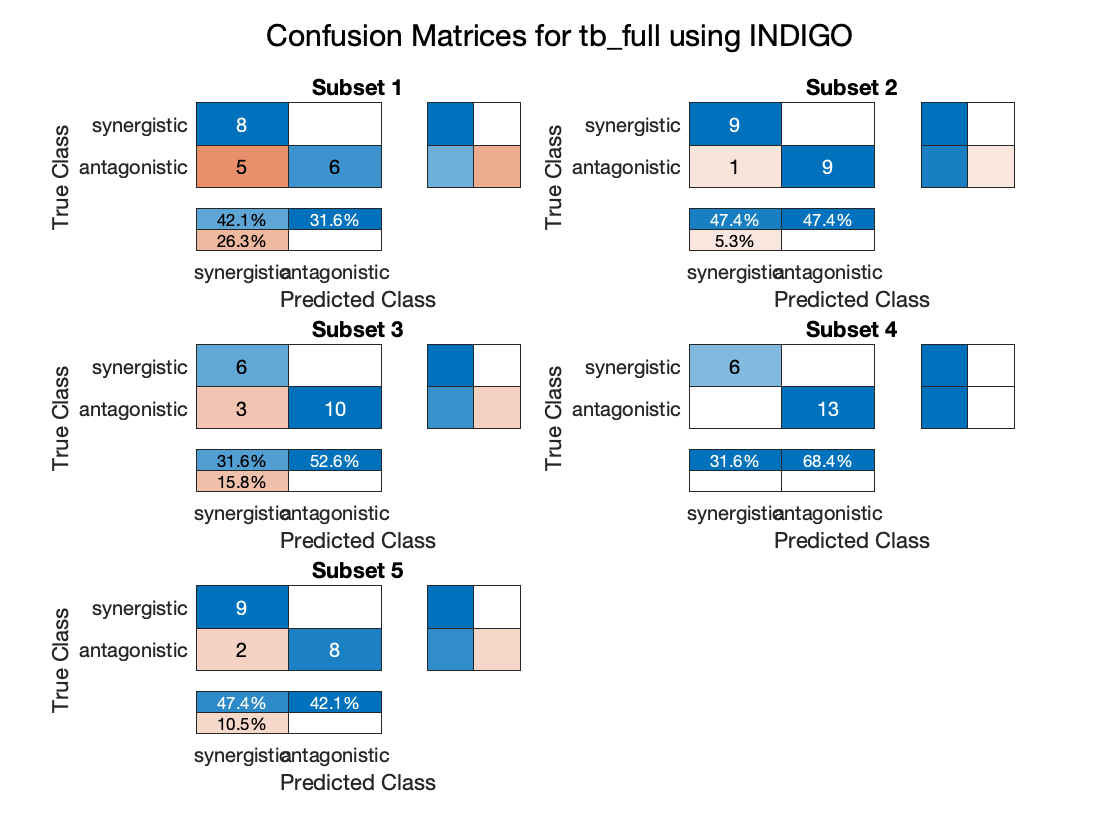

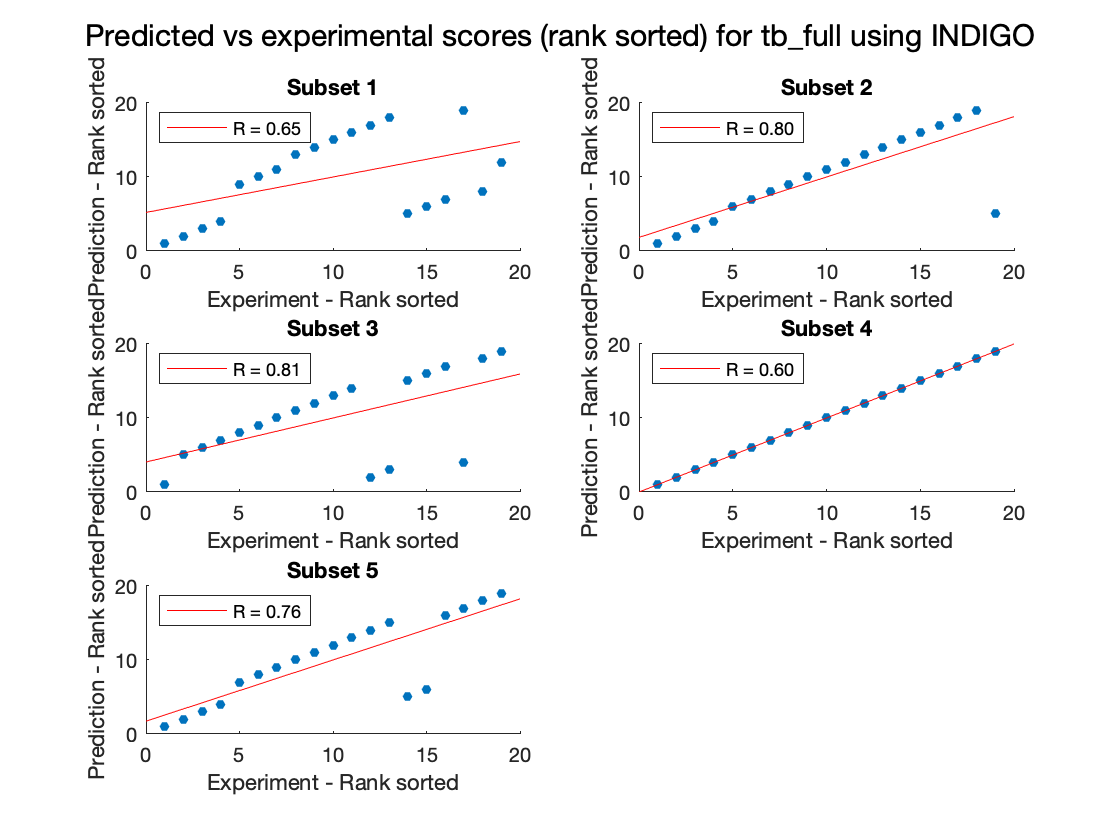

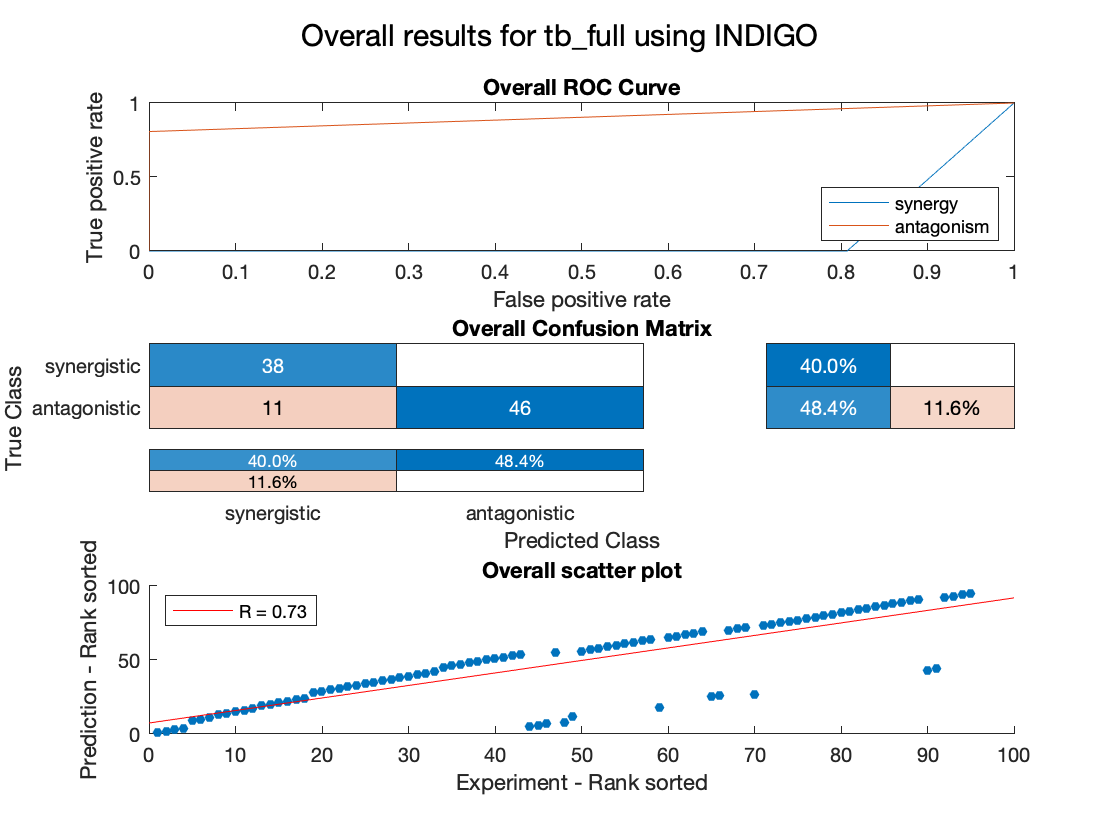

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         19         0.64763 

averagesTable = 12×1 table
                                  Value  
                                _________

    Interactions                       19
    R (rank)                      0.72285
    P value                     0.0018765
    Accuracy                      0.88421
    Absolute error                0.23158
    Precision (synergy)           0.80005
    Recall (synergy)                    1
    Precision (antagonism)              1
    Recall (antagonism)           0.80294
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)          0.098531
    AUC - ROC (antagonism)        0.90147


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        95
    R (rank)                       0.72929
    P value                     5.2755e-17
    Accuracy                       0.88421
    Absolute error                 0.23158
    Precision (synergy)            0.77551
    Recall (synergy)                     1
    Precision (antagonism)               1
    Recall (antagonism)            0.80702
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)           0.096491
    AUC - ROC (antagonism)         0.90351


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_full.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'
                'stlt2.xlsx'
                'st14028.xlsx'
                'pao1.xlsx'
                'pa14.xlsx'};
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;


indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 45.435264 seconds.
Run 2
Elapsed time is 43.256325 seconds.
Run 3
Elapsed time is 48.863609 seconds.
Run 4
Elapsed time is 46.403167 seconds.
Run 5
Elapsed time is 43.872251 seconds.


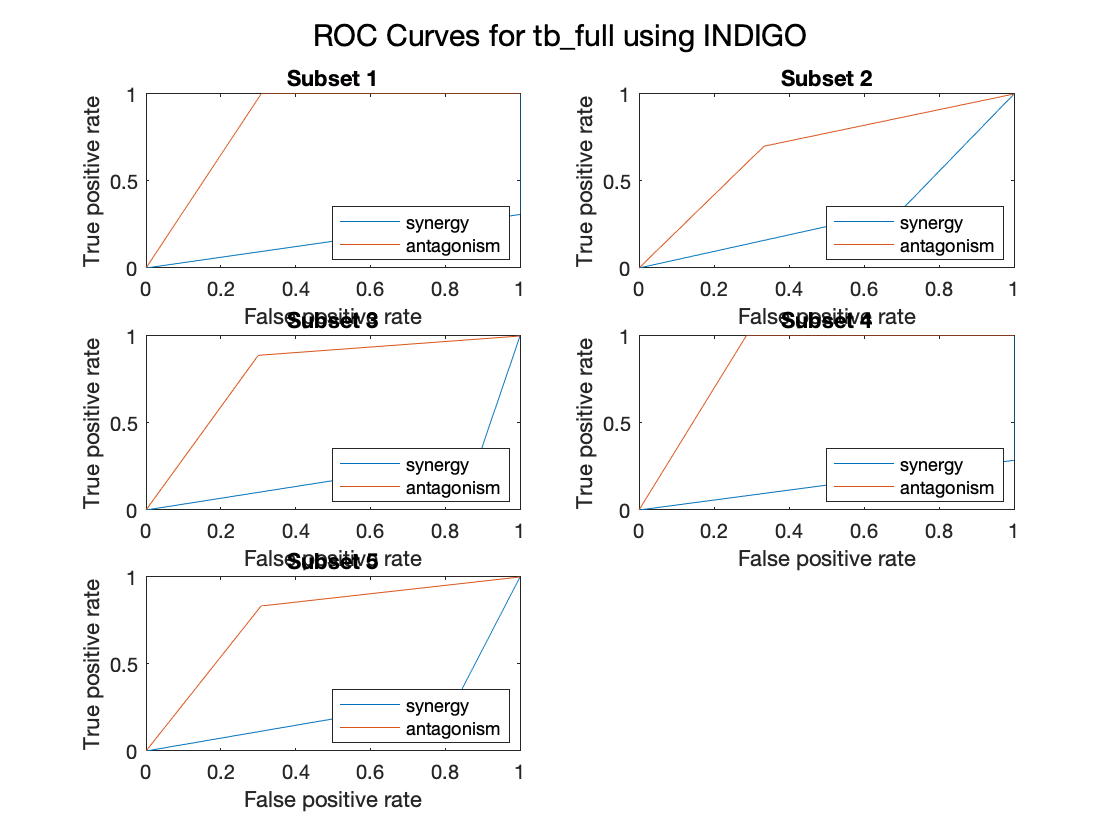

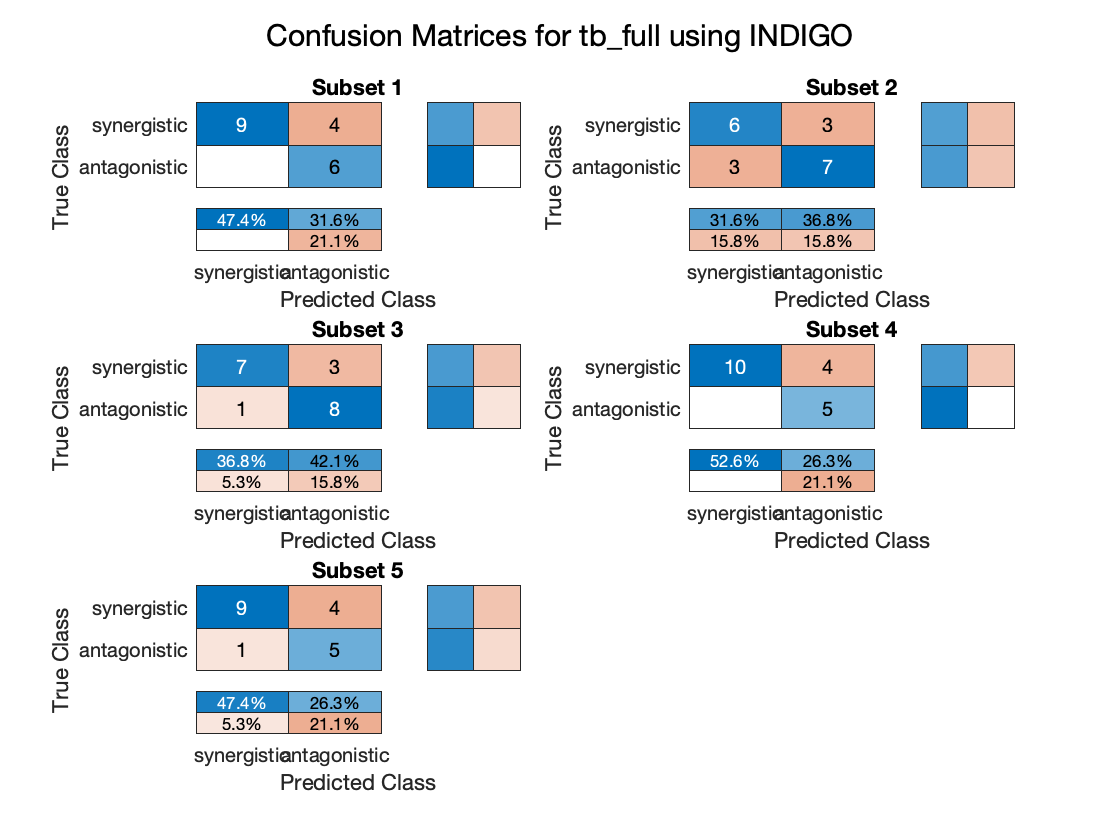

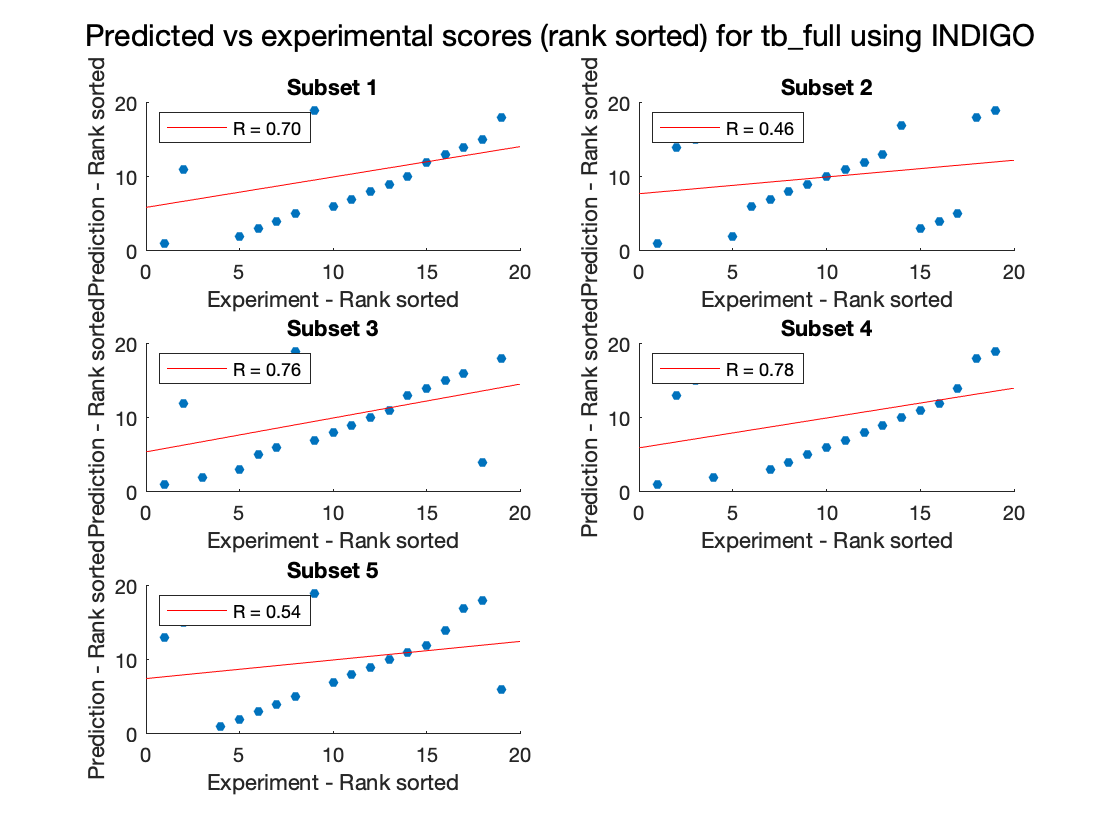

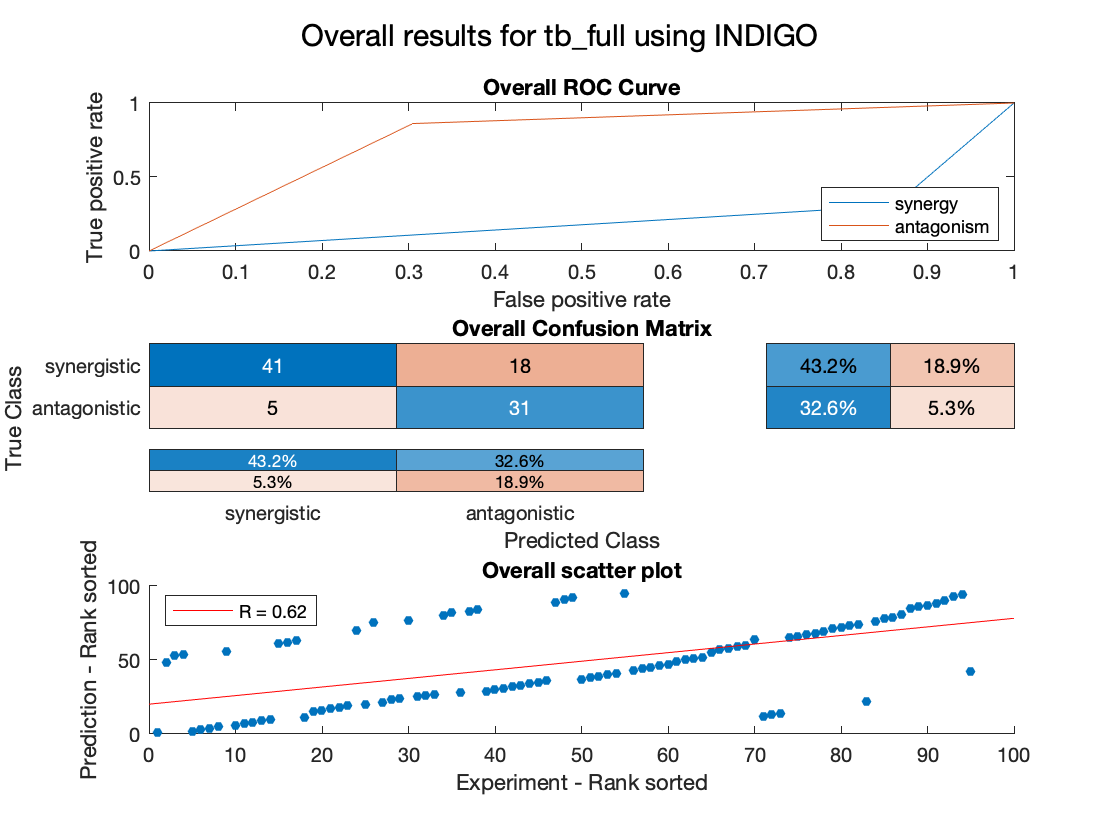

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         19         0.70164 

averagesTable = 12×1 table
                                  Value   
                                __________

    Interactions                        19
    R (rank)                       0.64575
    P value                        0.01351
    Accuracy                       0.75789
    Absolute error                 0.48421
    Precision (synergy)            0.88833
    Recall (synergy)               0.69311
    Precision (antagonism)         0.62768
    Recall (antagonism)            0.88444
    Guess Accuracy (p value)    2.5427e-20
    AUC - ROC (synergy)            0.21122
    AUC - ROC (antagonism)         0.78878


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        95
    R (rank)                       0.61878
    P value                     2.3435e-11
    Accuracy                       0.75789
    Absolute error                 0.48421
    Precision (synergy)             0.8913
    Recall (synergy)               0.69492
    Precision (antagonism)         0.63265
    Recall (antagonism)            0.86111
    Guess Accuracy (p value)    1.5508e-69
    AUC - ROC (synergy)            0.22199
    AUC - ROC (antagonism)         0.77801


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'tb_full.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'
                'stlt2.xlsx'
                'st14028.xlsx'
                'pao1.xlsx'
                'pa14.xlsx'};
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 45.865699 seconds.
Run 2
Elapsed time is 48.047771 seconds.
Run 3
Elapsed time is 52.249758 seconds.
Run 4
Elapsed time is 48.149508 seconds.
Run 5
Elapsed time is 44.910972 seconds.


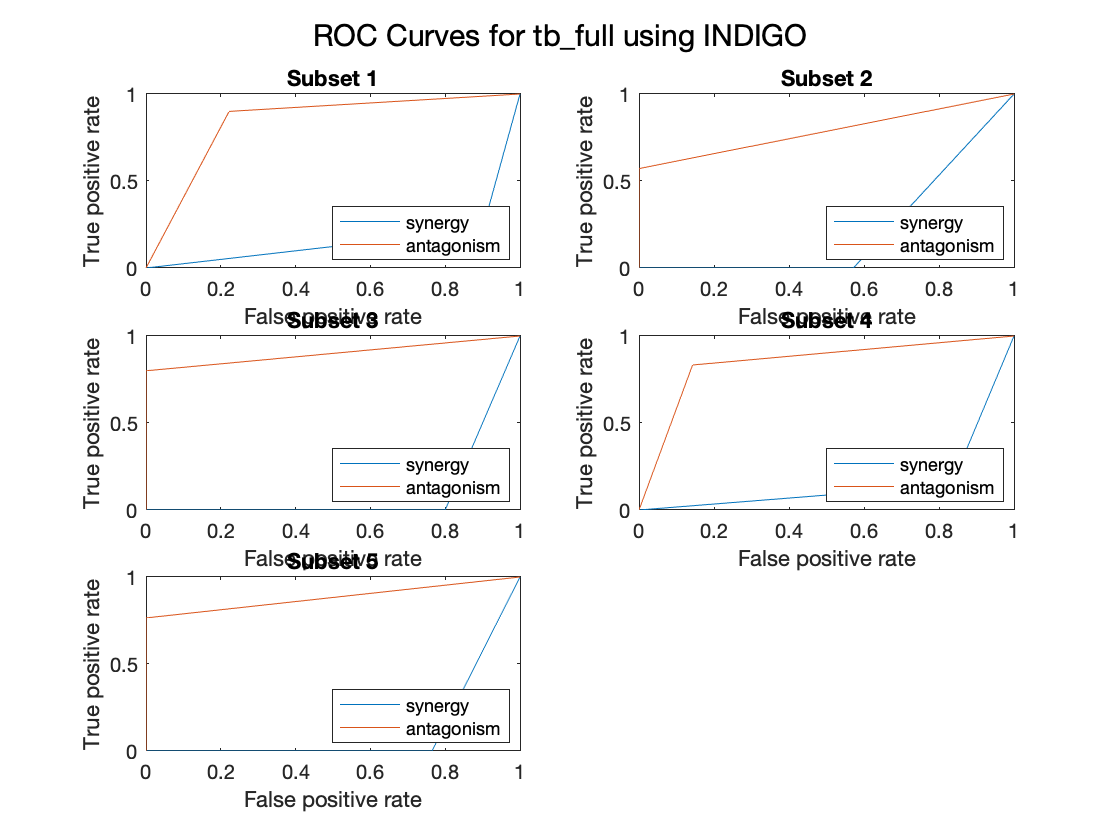

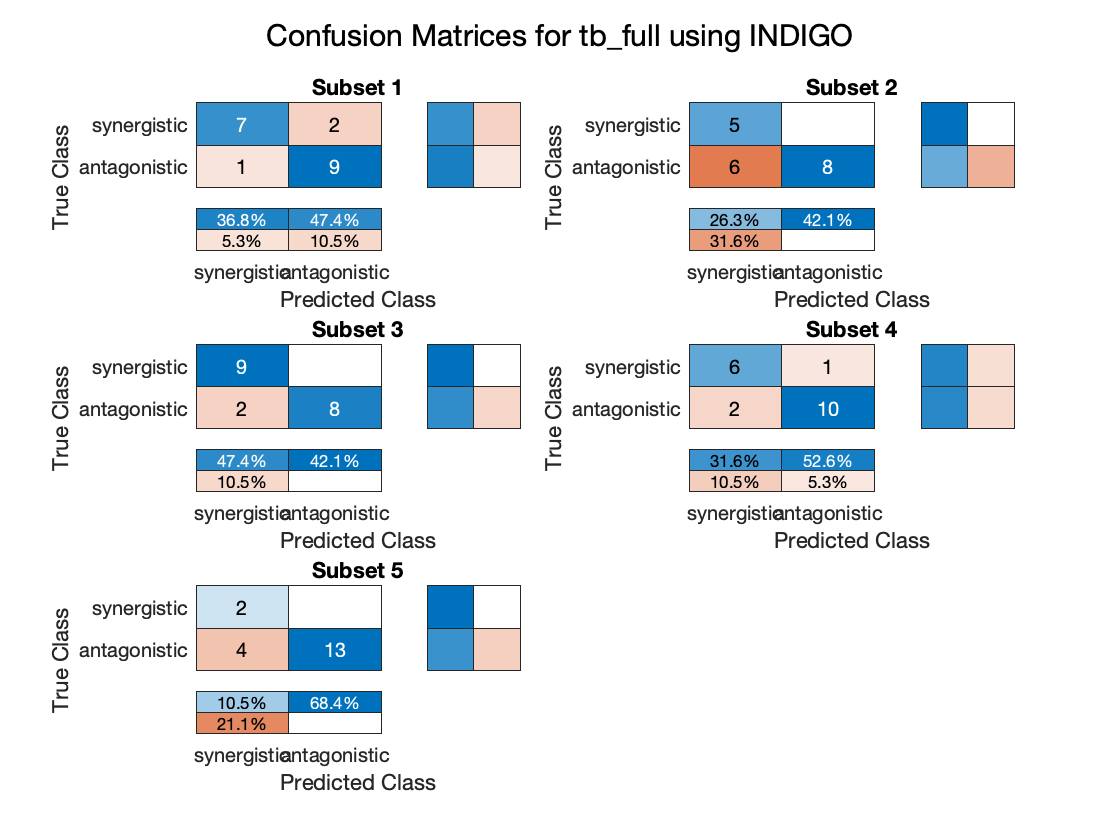

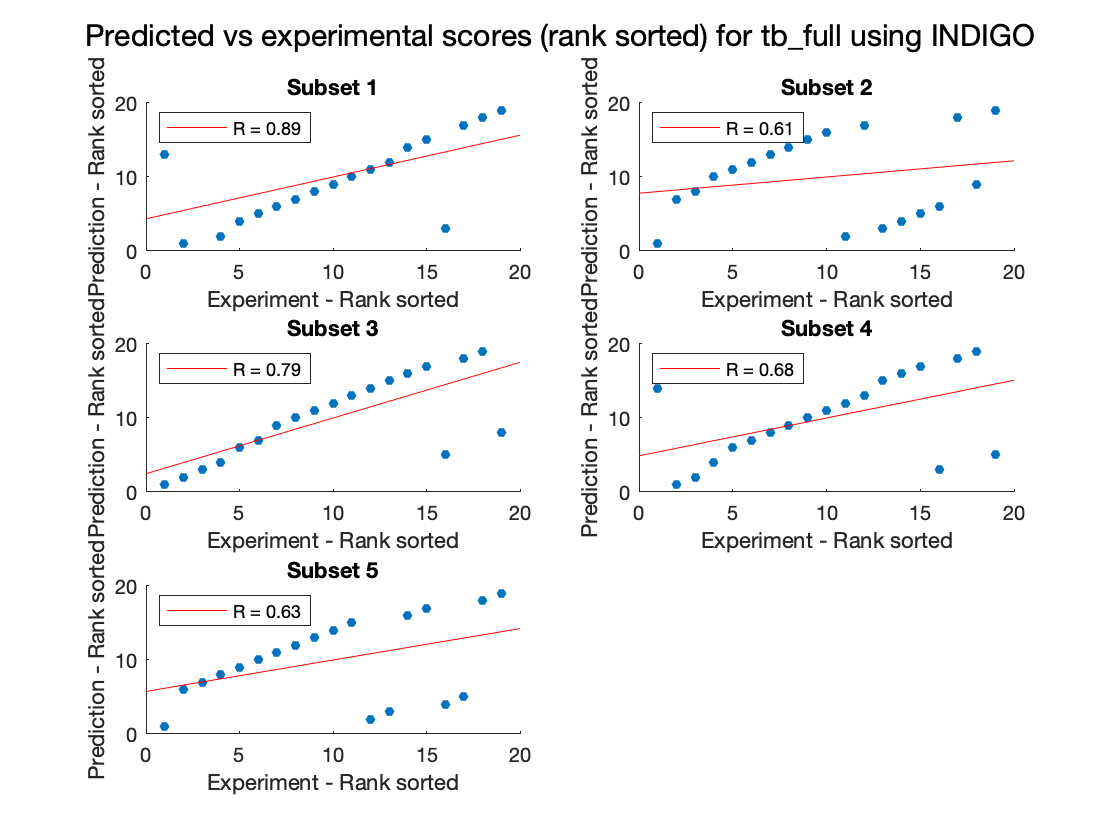

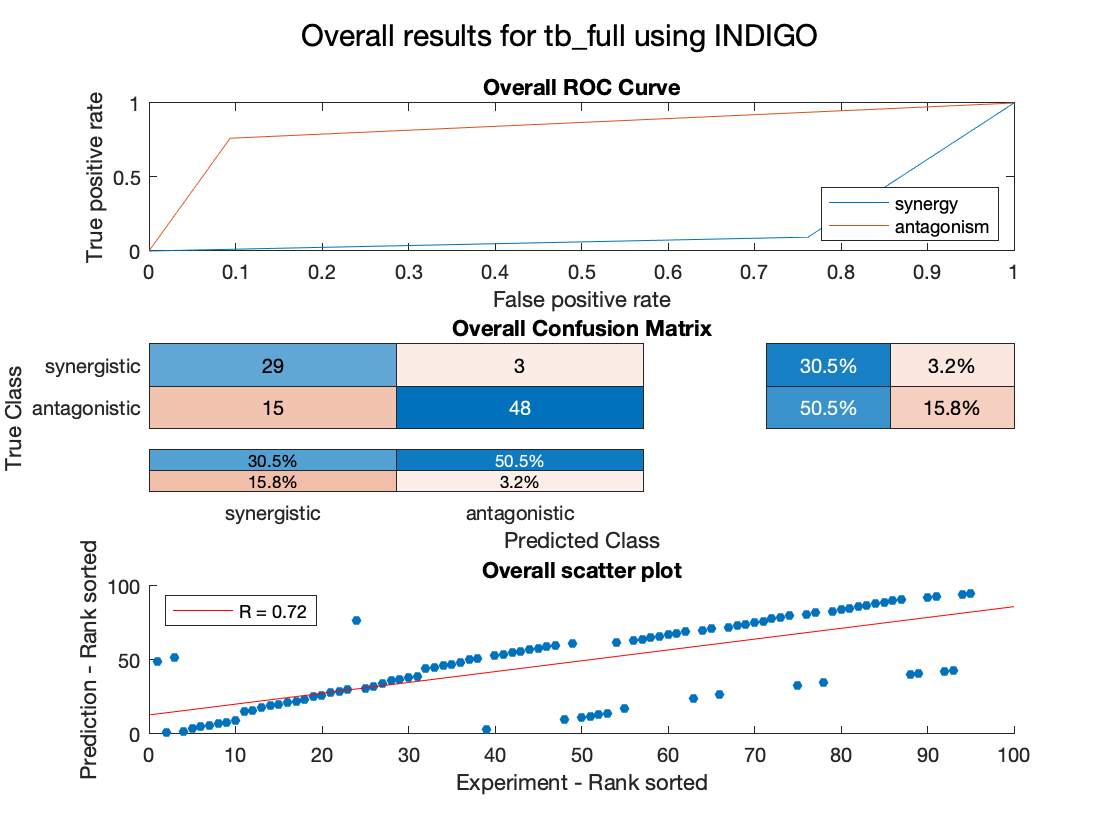

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         19         0.88762 

averagesTable = 12×1 table
                                  Value  
                                _________

    Interactions                       19
    R (rank)                      0.71943
    P value                     0.0021603
    Accuracy                      0.81053
    Absolute error                0.37895
    Precision (synergy)           0.64621
    Recall (synergy)              0.92698
    Precision (antagonism)        0.94545
    Recall (antagonism)           0.77389
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.14956
    AUC - ROC (antagonism)        0.85044


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        95
    R (rank)                       0.72035
    P value                     1.8989e-16
    Accuracy                       0.81053
    Absolute error                 0.37895
    Precision (synergy)            0.65909
    Recall (synergy)               0.90625
    Precision (antagonism)         0.94118
    Recall (antagonism)             0.7619
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.16592
    AUC - ROC (antagonism)         0.83408


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_full.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'};
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 21.579883 seconds.
Run 2
Elapsed time is 20.517250 seconds.
Run 3
Elapsed time is 19.016318 seconds.
Run 4
Elapsed time is 18.405348 seconds.
Run 5
Elapsed time is 18.008310 seconds.


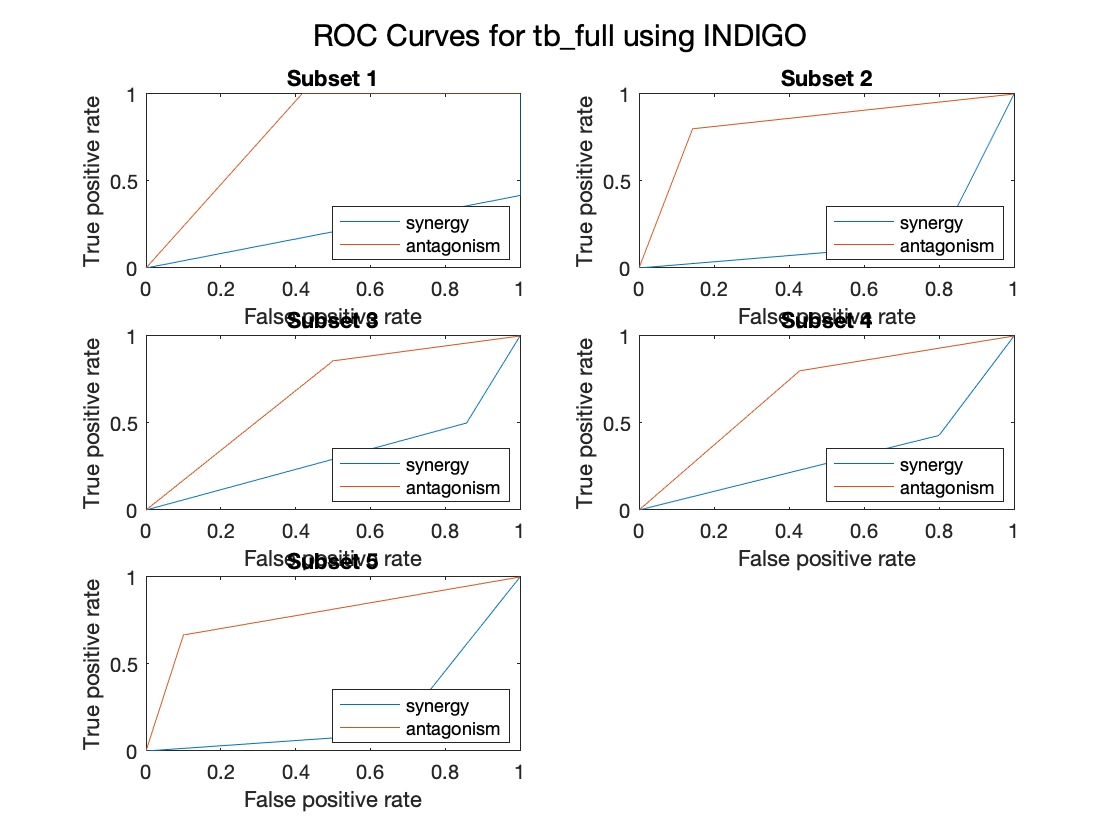

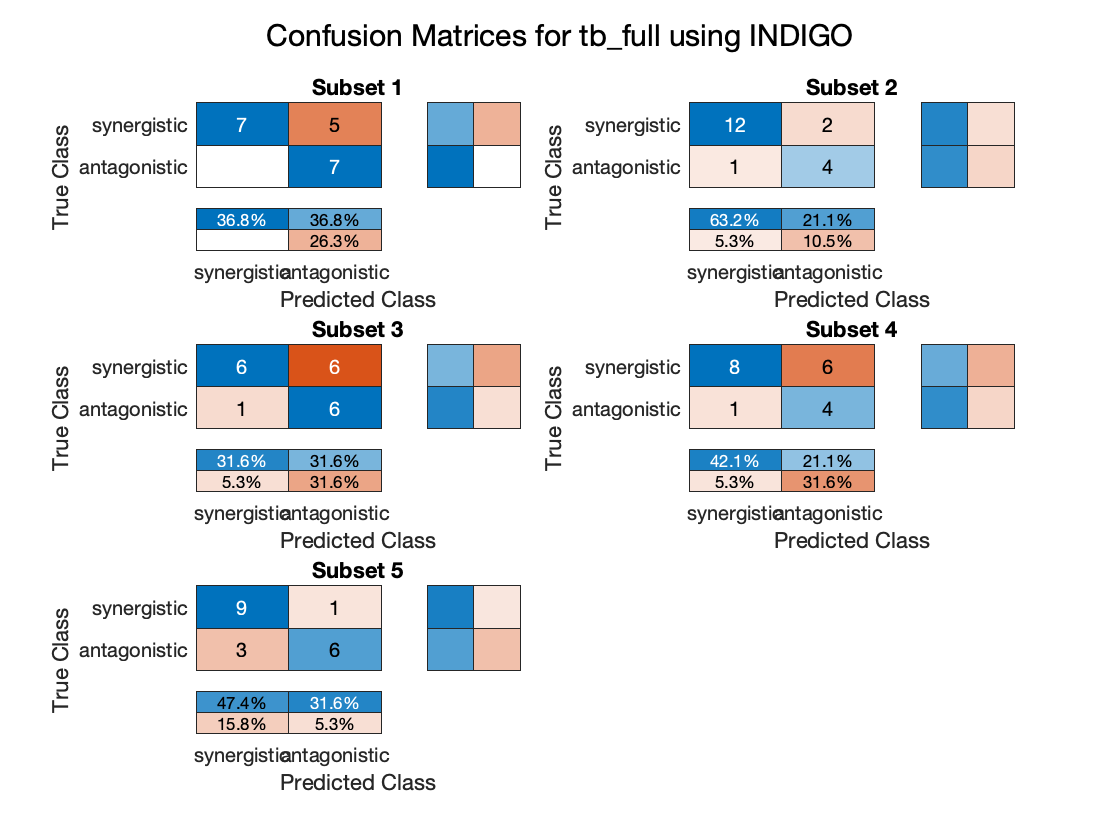

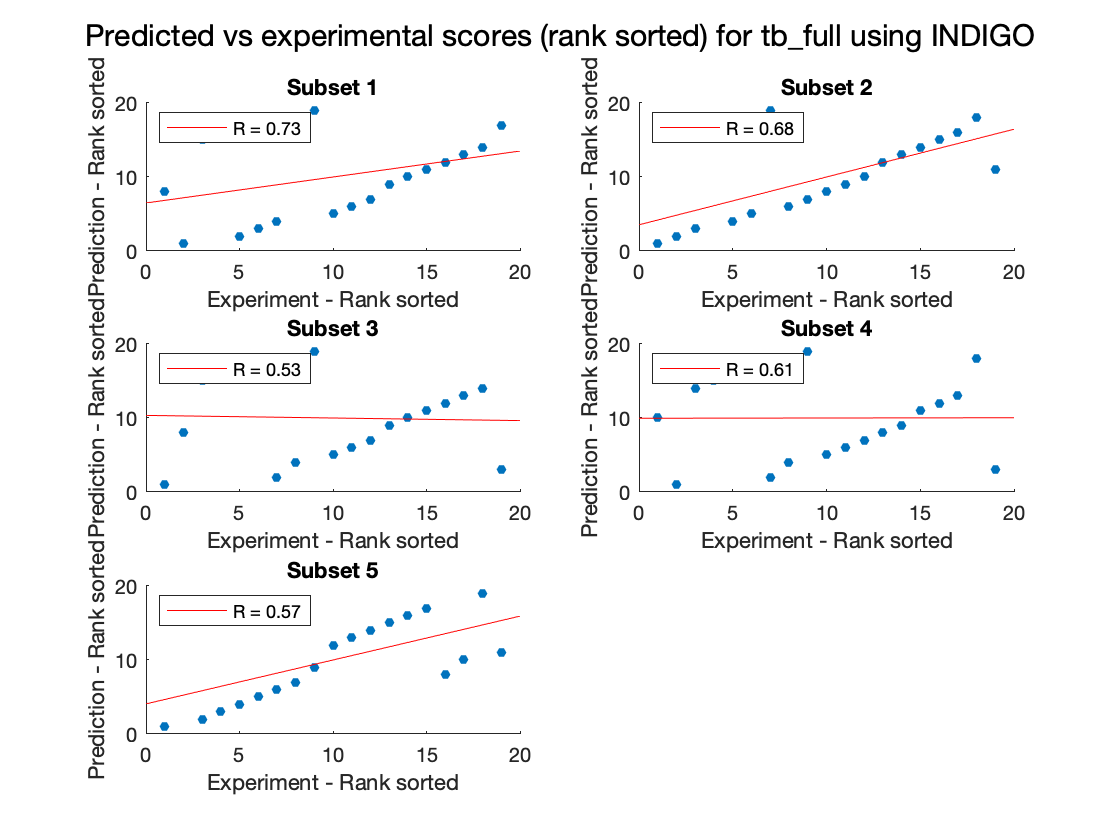

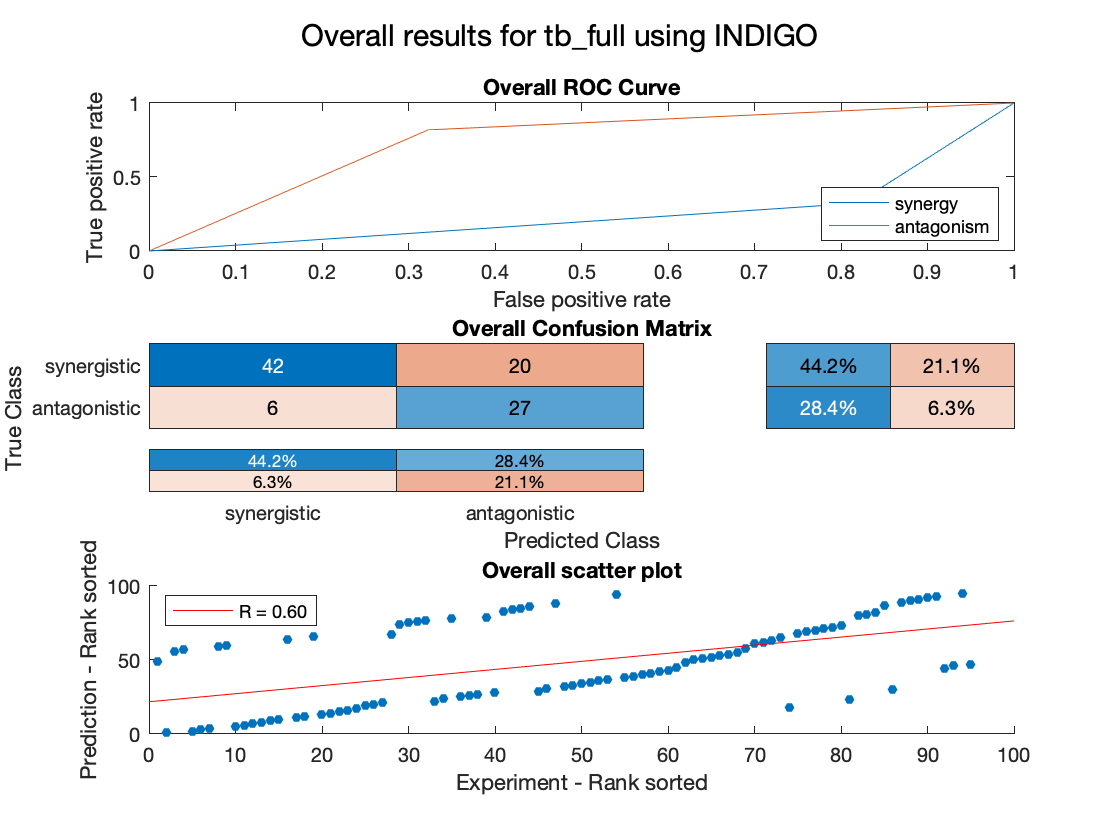

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         19         0.73313 

averagesTable = 12×1 table
                                  Value   
                                __________

    Interactions                        19
    R (rank)                       0.62403
    P value                      0.0075579
    Accuracy                       0.72632
    Absolute error                 0.54737
    Precision (synergy)            0.88382
    Recall (synergy)               0.68238
    Precision (antagonism)         0.60143
    Recall (antagonism)            0.82476
    Guess Accuracy (p value)    5.5489e-17
    AUC - ROC (synergy)            0.24643
    AUC - ROC (antagonism)         0.75357


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        95
    R (rank)                       0.60186
    P value                     1.1116e-10
    Accuracy                       0.72632
    Absolute error                 0.54737
    Precision (synergy)              0.875
    Recall (synergy)               0.67742
    Precision (antagonism)         0.57447
    Recall (antagonism)            0.81818
    Guess Accuracy (p value)    3.7249e-69
    AUC - ROC (synergy)             0.2522
    AUC - ROC (antagonism)          0.7478


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_full.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'};
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 20.163443 seconds.
Run 2
Elapsed time is 19.096658 seconds.
Run 3
Elapsed time is 20.981112 seconds.
Run 4
Elapsed time is 18.591975 seconds.
Run 5
Elapsed time is 19.106432 seconds.


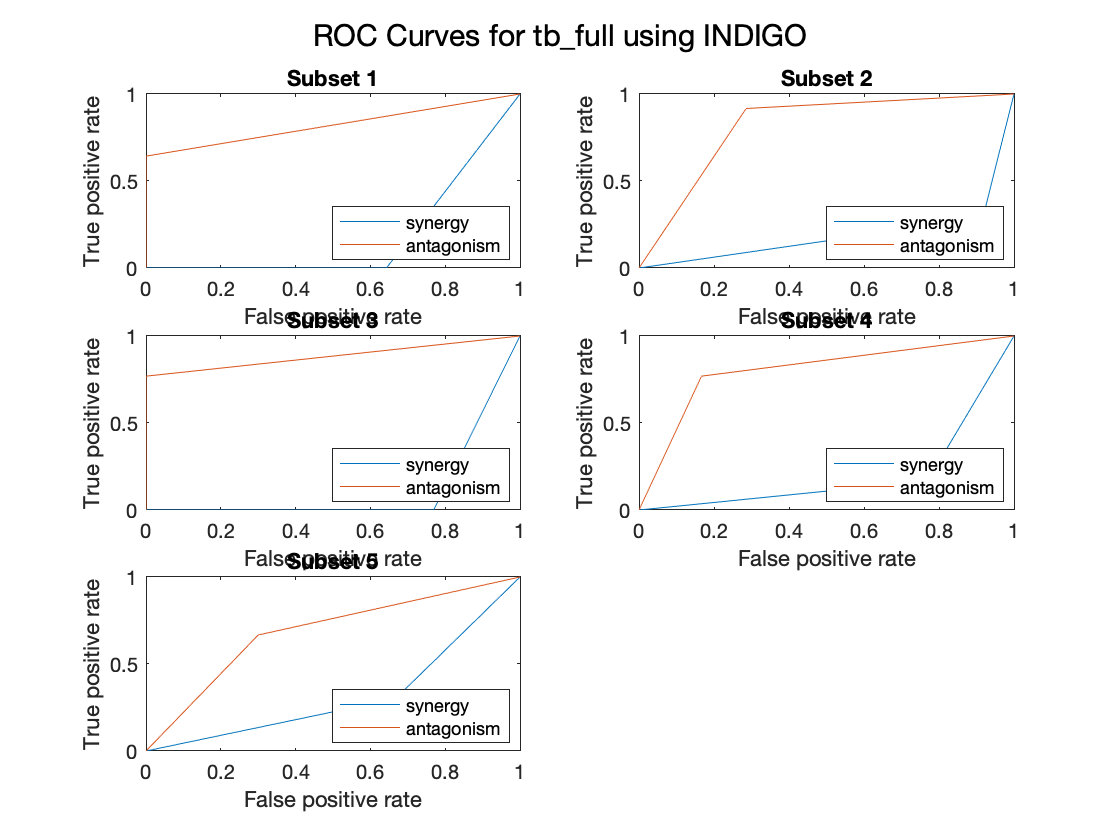

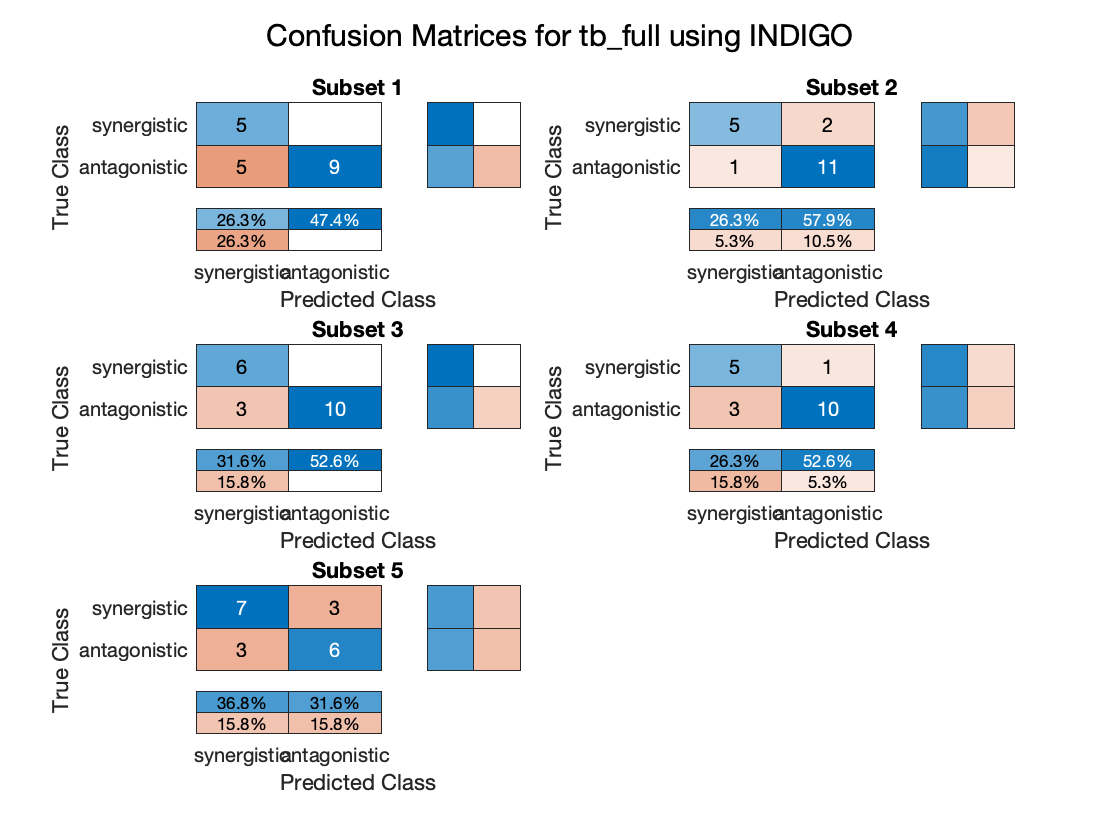

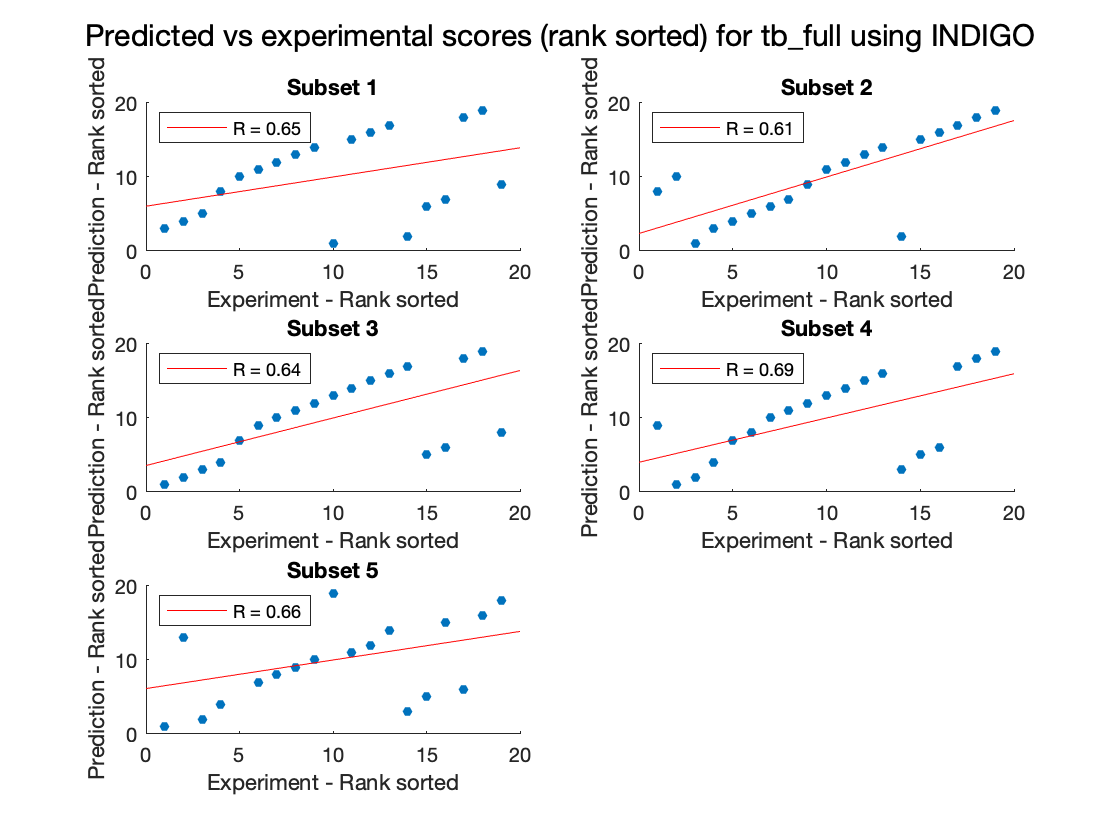

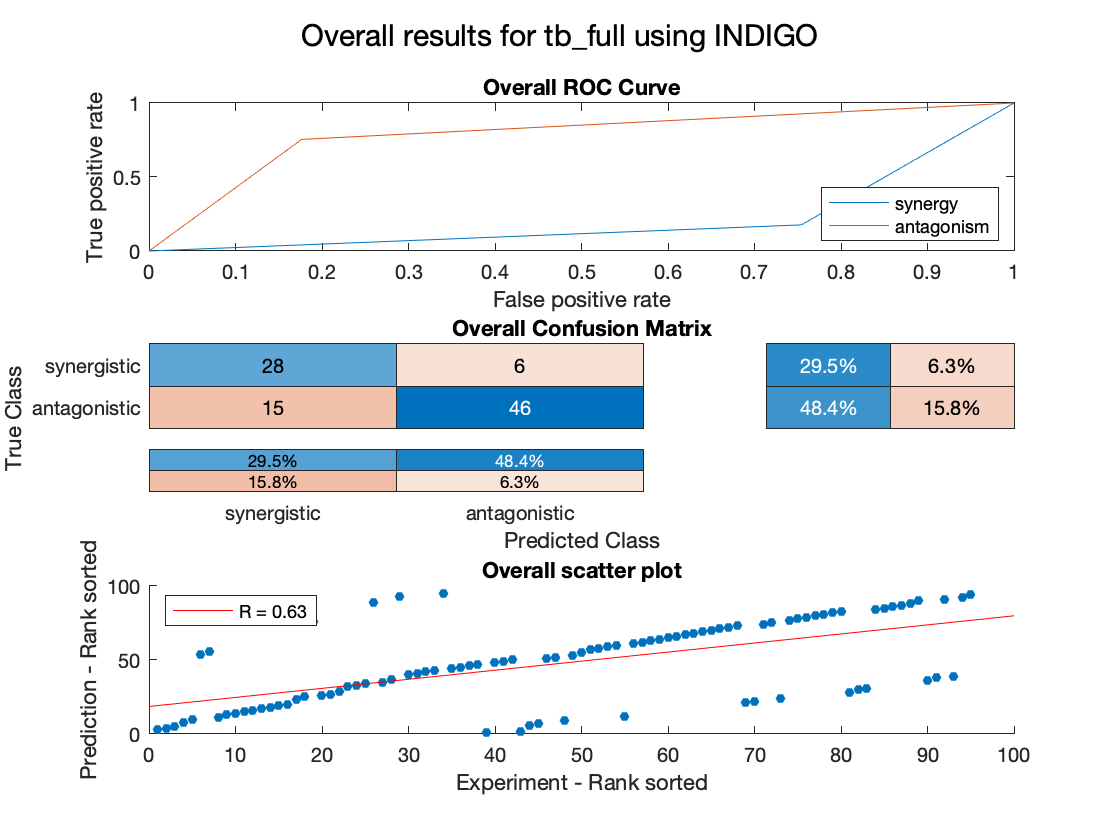

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         19           0.653   

averagesTable = 12×1 table
                                  Value  
                                _________

    Interactions                       19
    R (rank)                      0.64945
    P value                     0.0029472
    Accuracy                      0.77895
    Absolute error                0.44211
    Precision (synergy)             0.665
    Recall (synergy)              0.84952
    Precision (antagonism)        0.88438
    Recall (antagonism)           0.75293
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.19877
    AUC - ROC (antagonism)        0.80123


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        95
    R (rank)                       0.63195
    P value                     6.5266e-12
    Accuracy                       0.77895
    Absolute error                 0.44211
    Precision (synergy)            0.65116
    Recall (synergy)               0.82353
    Precision (antagonism)         0.88462
    Recall (antagonism)             0.7541
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.21119
    AUC - ROC (antagonism)         0.78881


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))